## Damped Harmonic Oscillator - Lagrangian Mechanics example

Simple damped oscillator example - to illustrate how we can use the Lagrangian approach to symbolically generate dynamic models for use in control

% Parameter values
params = struct;
syms omega_n zeta;
params.omega_n = 3;
params.zeta = 0.2;

% Coordinate functions
syms x(t);
v = diff(x,t);

## Form Lagrangian and get equations of motion

Here we form the Lagrangian (K.E - P.E) and apply Hamilton's principle of stationary/least action

% Kinetic Energy
T = 1/2 * v^2;

% Potential Energy
V = 1/2 * omega_n^2 * x^2;

% Lagrangian and action for this system:
syms t_1 t_2;

The dynamics of the mechanical system are given by the stationary points (usually minima) of the time integral of:

L = T - V

$$L(t) = \frac{{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}-\frac{{\omega_{n}}^{2}\,{x\left(t\right)}^{2}}{2}$$

% Generalised forces
% (for damping, external forces etc - anything nonconservative that we can't express with a potential energy)
Q = -2*zeta*omega_n * v;

We can find the equations giving the stationary points of S by requiring the functional derivative to be zero - then add the extra generalised forces

% Euler-Lagrange equation (using functional derivative)
EOM = functionalDerivative(L,x) == -Q

$$EOM(t) = -\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-x\left(t\right)\,{\omega_{n}}^{2}=2\,\omega_{n}\,\zeta \,\frac{\partial }{\partial t}x\left(t\right)$$

## Natural frequency and damping factor

To check we have the expected ODE for the oscillator, we can calculate the natural frequency and damping

% Get the characteristic polynomial of the ODE
syms s; 
EOM_s = subs(EOM, [diff(x(t),t,t);diff(x(t),t);x], [s^2;s;1]);
EOM_poly = lhs(EOM_s) - rhs(EOM_s)

$$EOM\_poly(t) = -{\omega_{n}}^{2}-2\,\zeta \,\omega_{n}\,s-s^{2}$$

% Sub in param values and extract coefficients from standard form polynomial
EOM_poly = subs(EOM_poly, params);
c = double(coeffs(EOM_poly, s));
syms c_k;
c_k = sym(c(end-2)/c(end));
c_d = sym(c(end-1)/c(end));
omega_n = sqrt(c_k)

$$omega\_n = 3$$

zeta = c_d/2/omega_n

$$zeta = \frac{1}{5}$$

This natural frequency and damping factor should be the same as those defined at the top of the script!

## Analytical solution of equations of motion

In this case, since the ODE is linear, we can find analytical solutions for the time response

% General Solution
xx(t) = dsolve(EOM)

$$xx(t) = C_{1}\,{\mathrm{e}}^{t\,\left(\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\omega_{n}\,\zeta \right)}+C_{2}\,{\mathrm{e}}^{-t\,\left(\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}+\omega_{n}\,\zeta \right)}$$

For a particular solution we can apply some initial conditions:

% Particular solution
BC = [x(0) == 2, v(0) == 2];
y(t) = dsolve([EOM, BC])

$$y(t) = \frac{{\mathrm{e}}^{t\,\left(\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\omega_{n}\,\zeta \right)}\,\left(\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}+\omega_{n}\,\zeta +1\right)}{\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}}-\frac{{\mathrm{e}}^{-t\,\left(\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}+\omega_{n}\,\zeta \right)}\,\left(\omega_{n}\,\zeta -\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}+1\right)}{\omega_{n}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}}$$

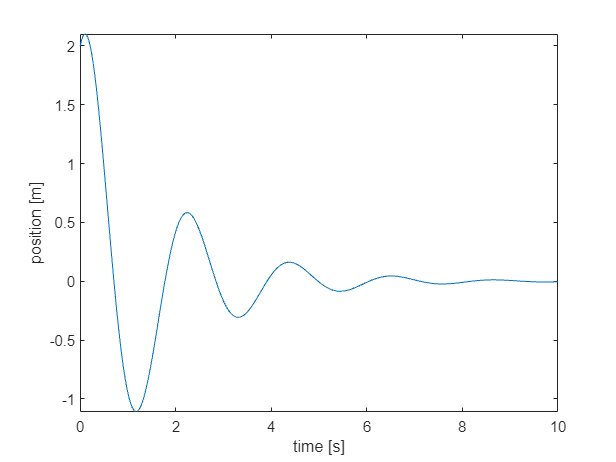

y = subs(y, params);        % sub in parameter values so we can plot solution
fplot(y,[0,10]);
xlabel('time [s]'); ylabel('position [m]');

## Numerical solution of equations of motion

We can also find numerical solutions to the EOM by using Matlab's IVP solvers like ode45. We must first convert the equations to first order:

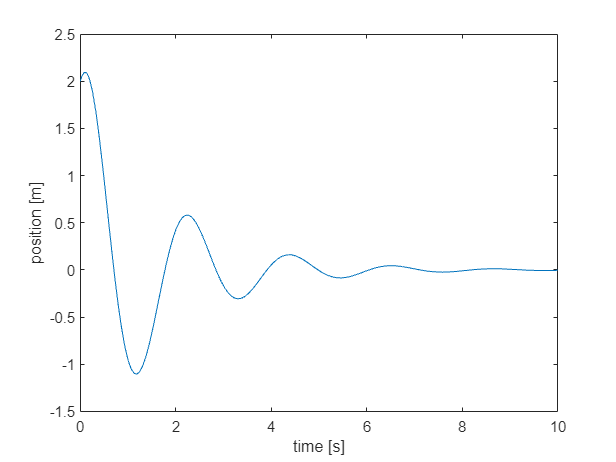

% Numerical solution using ode45
F = odeToVectorField(EOM);

% Code generate a function to evaluate the RHS of these first order ODEs
F = subs(F, params);
f = matlabFunction(F,'vars',{'t','Y'});

% Numerical solution using ode45
opts = odeset('RelTol', 1e-6);
odesol = ode45(f, [0,10], [2,2], opts);
plot(odesol.x, odesol.y(1,:));
xlabel('time [s]'); ylabel('position [m]');

Hopefully, this is the same as the analytical solution above! 

Normally this is more useful than the analytical method, since we're rarely lucky enough to have an analytically solvable system of ODEs

### Simulink Model

Finally, we automatically generate a simulink model for the system. Let's convert the system to first order, but this time keep the variable names

% Convert to a first order system of equations
[F,S] = stateSpaceEquations(EOM,{x});
F = subs(F, params);

The following function creates a simple simulink model for these ODEs.

Note that if you add external control inputs in your EOM, you should specify them in the 3rd argument and the simulink model will include these as inputs to the corresponding block.

IC = '[2;2]';    %  Initial conditions for simulink (so we can run the model)
openLoopModel(F, S, [], IC, 'oscillator');